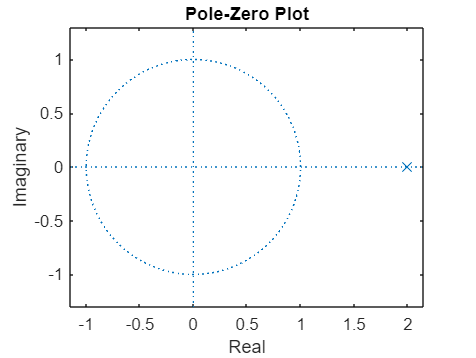

%1a
% Define the value of R0
R0 = 2; % Replace with your desired value

% Define the transfer function H1(z)
numerator = 1;
denominator = [1, -R0];

% Calculate the poles and zeros
poles = roots(denominator);
zeros = roots(numerator);

% Plot the pole-zero plot
figure;
zplane(zeros, poles);
title('Pole-Zero Plot');
xlabel('Real');
ylabel('Imaginary');

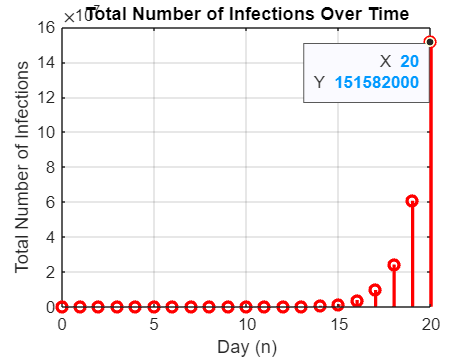

% Number of days
n_max = 20;

% Generate the sequence of new daily infections (using R0 = 2.5)
R0 = 2.5;
y = zeros(1, n_max + 1);
y(1) = 1; % Initial infection
for n = 2:n_max + 1
    y(n) = R0 * y(n - 1);
end

% Design an integrator filter (discrete-time accumulator)
integrator_filter = ones(1, n_max + 1);

% Apply the integrator filter to obtain the total number of infections
total_infections = conv(y, integrator_filter, 'full');

% Extract the relevant part for the first 20 days
total_infections = total_infections(1:n_max + 1);

% Plot the results
figure;
stem(0:n_max, total_infections, 'r', 'LineWidth', 2);
title('Total Number of Infections Over Time');
xlabel('Day (n)');
ylabel('Total Number of Infections');
grid on;

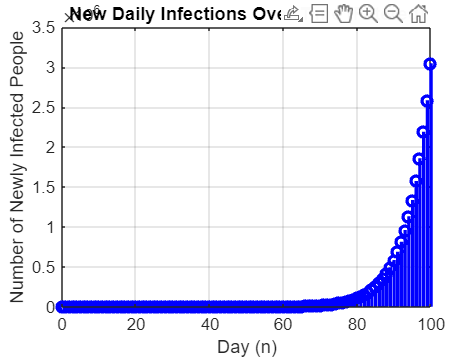

% Given coefficients for M = 12
ak = [.1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1];
M = length(ak);

% Number of days
n_max = 100;

% Initialize the sequence
y = zeros(1, n_max + 1);
y(1) = 1; % Kronecker delta input

% Implement the filter using the difference equation
for n = 2:n_max + 1
    for k = 1:M
        if n - k > 0
            y(n) = y(n) + ak(k) * y(n - k);
        end
    end
end

% Plot the results
figure;
stem(0:n_max, y, 'b', 'LineWidth', 2);
title('New Daily Infections Over Time (Filtered)');
xlabel('Day (n)');
ylabel('Number of Newly Infected People');
grid on;

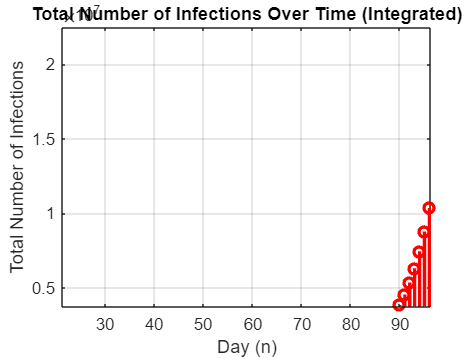

Number of days to reach 1 million new daily infections: 95


% Implement the integrator filter (discrete-time accumulator)
integrator_filter = ones(1, n_max + 1);
total_infections = conv(y, integrator_filter, 'full');

% Extract the relevant part for the first 100 days
total_infections = total_infections(1:n_max + 1);

% Plot the results
figure;
stem(0:n_max, total_infections, 'r', 'LineWidth', 2);
title('Total Number of Infections Over Time (Integrated)');
xlabel('Day (n)');
ylabel('Total Number of Infections');
grid on;

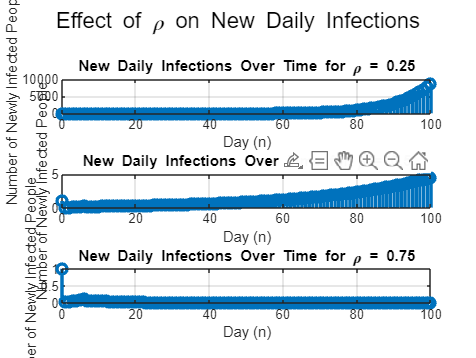

% Given coefficients for M = 12
ak = [.1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1];
M = length(ak);

% Number of days
n_max = 100;

% Values of rho to test
rho_values = [0.25, 0.50, 0.75];

% Plot results for each rho
figure;

for i = 1:length(rho_values)
    rho = rho_values(i);

    % Initialize the sequence
    y = zeros(1, n_max + 1);
    y(1) = 1; % Kronecker delta input

    % Implement the IIR filter with the given transfer function
    for n = 2:n_max + 1
        for k = 1:M
            if n - k > 0
                y(n) = y(n) + (1 - rho) * ak(k) * y(n - k);
            end
        end
    end

    % Plot the results
    subplot(length(rho_values), 1, i);
    stem(0:n_max, y, 'LineWidth', 2);
    title(['New Daily Infections Over Time for \rho = ', num2str(rho)]);
    xlabel('Day (n)');
    ylabel('Number of Newly Infected People');
    grid on;
end

% Adjust subplot layout
sgtitle('Effect of \rho on New Daily Infections');

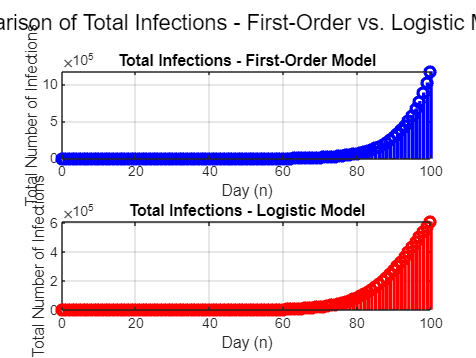

% Given parameters
R0 = 1.15;
K = 1e6;
n_max = 100;

% Initialize arrays for storing results
total_infections_first_order = zeros(1, n_max + 1);
total_infections_logistic = zeros(1, n_max + 1);

% First-order model
for n = 1:n_max + 1
    total_infections_first_order(n) = R0^(n-1);
end

% Logistic model
for n = 1:n_max + 1
    total_infections_logistic(n) = K / (1 + ((K * (R0 - 1) - R0) / (R0 - 1)) * R0^(-(n+1)));
end

% Plot the results
figure;
subplot(2, 1, 1);
stem(0:n_max, total_infections_first_order, 'b', 'LineWidth', 2);
title('Total Infections - First-Order Model');
xlabel('Day (n)');
ylabel('Total Number of Infections');
grid on;

subplot(2, 1, 2);
stem(0:n_max, total_infections_logistic, 'r', 'LineWidth', 2);
title('Total Infections - Logistic Model');
xlabel('Day (n)');
ylabel('Total Number of Infections');
grid on;

sgtitle('Comparison of Total Infections - First-Order vs. Logistic Models');

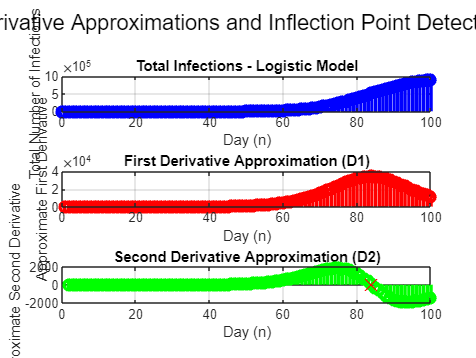

% Given parameters
R0 = 1.15;
K = 1e6;
n_max = 100;

% Initialize arrays for storing results
total_infections_logistic = zeros(1, n_max + 1);

% Logistic model
for n = 1:n_max + 1
    total_infections_logistic(n) = (K / (1 + ((K * (R0 - 1) - R0) ) * R0^(-(n+1))))-1/(R0-1);
end

% Derivative FIR filters
D1 = [1, -1];
D2 = [1, -2, 1];

% Apply FIR filters to approximate derivatives
derivative_1 = conv(total_infections_logistic, D1, 'valid');
derivative_2 = conv(total_infections_logistic, D2, 'valid');

% Find zero-crossings of the second derivative
inflection_point_index = find(derivative_2(1:end-1) .* derivative_2(2:end) <= 0, 1);

% Plot the results
figure;
subplot(3, 1, 1);
stem(0:n_max, total_infections_logistic, 'b', 'LineWidth', 2);
title('Total Infections - Logistic Model');
xlabel('Day (n)');
ylabel('Total Number of Infections');
grid on;

subplot(3, 1, 2);
stem(1:n_max, derivative_1, 'r', 'LineWidth', 2);
title('First Derivative Approximation (D1)');
xlabel('Day (n)');
ylabel('Approximate First Derivative');
grid on;

subplot(3, 1, 3);
stem(2:n_max, derivative_2, 'g', 'LineWidth', 2);
hold on;
plot(inflection_point_index + 1, 0, 'rx', 'MarkerSize', 10);
hold off;
title('Second Derivative Approximation (D2)');
xlabel('Day (n)');
ylabel('Approximate Second Derivative');
grid on;

sgtitle('Derivative Approximations and Inflection Point Detection');


% Find the point of inflection using the global maximum of the first derivative
[~, max_derivative_index] = max(derivative_1);
inflection_point_max_derivative = max_derivative_index;

% Display the results
disp(['Inflection Point (Max First Derivative): Day ', num2str(inflection_point_max_derivative)]);

Inflection Point (Max First Derivative): Day 84



% Find the point of inflection using the zero-crossing of the second derivative
inflection_point_zero_crossing = inflection_point_index + 1;

% Display the results
disp(['Inflection Point (Zero-Crossing Second Derivative): Day ', num2str(inflection_point_zero_crossing)]);

Inflection Point (Zero-Crossing Second Derivative): Day 84


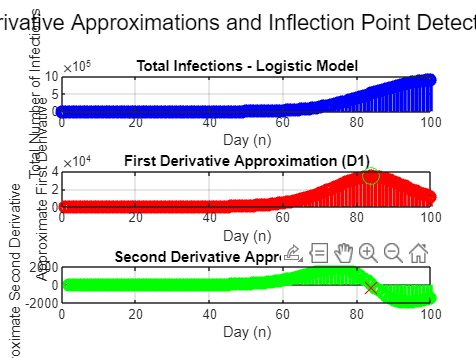


% Plot the results
figure;
subplot(3, 1, 1);
stem(0:n_max, total_infections_logistic, 'b', 'LineWidth', 2);
title('Total Infections - Logistic Model');
xlabel('Day (n)');
ylabel('Total Number of Infections');
grid on;

subplot(3, 1, 2);
stem(1:n_max, derivative_1, 'r', 'LineWidth', 2);
hold on;
plot(inflection_point_max_derivative, derivative_1(inflection_point_max_derivative), 'go', 'MarkerSize', 10);
hold off;
title('First Derivative Approximation (D1)');
xlabel('Day (n)');
ylabel('Approximate First Derivative');
grid on;

subplot(3, 1, 3);
stem(2:n_max, derivative_2, 'g', 'LineWidth', 2);
hold on;
plot(inflection_point_zero_crossing, derivative_2(inflection_point_zero_crossing), 'rx', 'MarkerSize', 10);
hold off;
title('Second Derivative Approximation (D2)');
xlabel('Day (n)');
ylabel('Approximate Second Derivative');
grid on;

sgtitle('Derivative Approximations and Inflection Point Detection');